# **Deriving Equations of Motion of Double Pendulum **

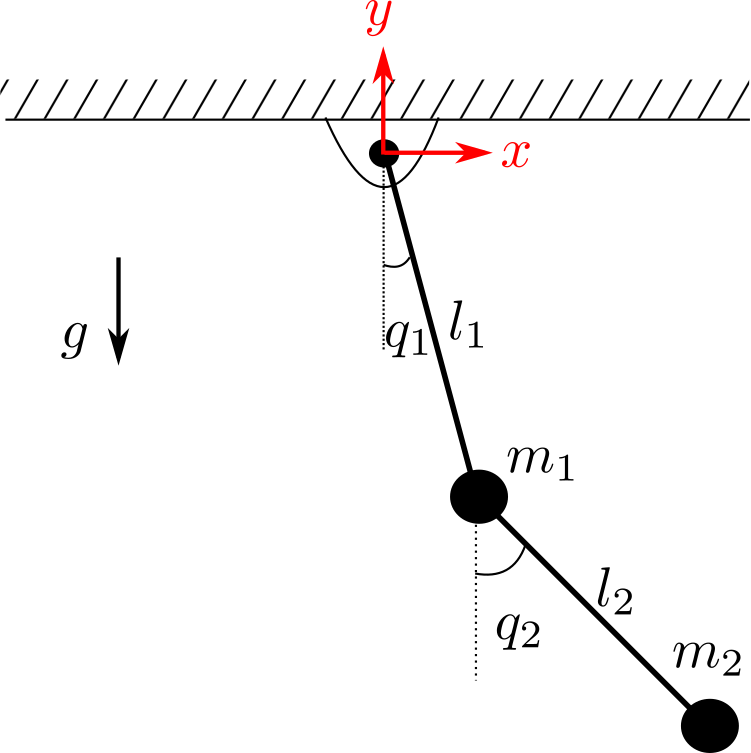

Derive the equations of motion of this system which is in the form of:


$$M(q) \ddot q + C(q, \dot q) \dot q + G(q) = 0$$
 

What are the formulas for matrices $M(q), C(q, \dot q)$ and $G(q)$? 

syms m1 m2 l1 l2 g 
syms q1 q2 dq1 dq2 ddq1 ddq2

# Kinematics**: **

**Position and velocity of m1:**

disp('-------------------------')

-------------------------


disp('Position and velocity of m1:')

Position and velocity of m1:


x1 = l1 * sin(q1)

$$x1 = l_{1}\,\sin\left(q_{1}\right)$$

y1 = -l1 * cos(q1)
dx1 = diff(x1, q1) * dq1

$$dx1 = {\mathrm{dq}}_{1}\,l_{1}\,\cos\left(q_{1}\right)$$

dy1 = diff(y1, q1) * dq1

**Position and velocity of m2:**

disp('-------------------------')

-------------------------


disp('Position and velocity of m2:')

Position and velocity of m2:


x2 = l1 * sin(q1) + l2 * sin(q2)

$$x2 = l_{1}\,\sin\left(q_{1}\right)+l_{2}\,\sin\left(q_{2}\right)$$

y2 = -l1 * cos(q1) - l2 * cos(q2)
dx2 = diff(x2, q1)*dq1 + diff(x2, q2)*dq2
dy2 = diff(y2, q1)*dq1 + diff(y2, q2)*dq2

# Dynamics:

**Kinetic and potential energies of m1:**

disp('-------------------------')

-------------------------


disp('Kinetic and potential energies of m1:')

Kinetic and potential energies of m1:


T1 = 0.5 * m1 * (dx1^2 + dx2^2)
V1 = - m1 * y1 * g
T1 = simplify(T1) % To simplify the symbolic equations
V1 = simplify(V1)

**Kinetic and potential energies of m2:**

disp('-------------------------')

-------------------------


disp('Kinetic and potential energies of m2:')

Kinetic and potential energies of m2:


T2 =  0.5 * m2 * (dx2^2 + dy2^2)
V2 =  - m2 * y2 * g
T2 = simplify(T2, 'Steps', 50) % sometimes you need to 'increase' the simplification level
V2 = simplify(V2)

## Recall Lagrangian:


$$L(q, \dot q) = T(q, \dot q) - V(q)$$


## Lagrange equations of motion:

$\frac{d}{dt}(\frac{\partial L}{\partial \dot q_i }) - \frac{\partial L}{\partial q_i} = 0$           for i = 1, 2

disp('-------------------------')

-------------------------


disp('Cacluate the Lagrangian of the system: ')

Cacluate the Lagrangian of the system: 


T = T1 + T2 % this is the total kinetic energy of the system 
T = simplify(T, 'Steps',50)
V = V1 + V2 % this is the total kinetic energy of the system
V = simplify(V, 'Steps',50)
L = T - V % this is the lagrangian of the system 

We use $dLddq$ as short for $\frac{\partial L}{\partial \dot q}$ and $dLdq$ for $\frac{\partial L}{\partial q}$.     

disp('-------------------------')

-------------------------


disp('Calculate the partial derivatives of Lagrangian:')

Calculate the partial derivatives of Lagrangian:


dLddq1 = diff(L, dq1); % ???
dLddq2 = diff(L, dq2); % ???
dLdq1 = diff(L, q1); % *dq1 ?
dLdq2 = diff(L, q2); % *dq2 ?
dLddq1 = simplify(dLddq1)
dLddq2 = simplify(dLdd2)
dLdq1 = simplify(dLdq1)
dLdq2 = simplify(dLdq2)

We use dLddq_dt for $\frac{d}{dt}(\frac{\partial L}{\partial \dot q})$

This is to calculate the formula for $\frac{d}{dt}(\frac{\partial L}{\partial \dot q_1})$:


disp('-------------------------')

-------------------------


dLddq1_dt = diff(dLddq1, q1) * dq1 + ? %continue: note that dLddq1 is a function of q1, q2, dq1, dq2

This is to calculate the formula for $\frac{d}{dt}(\frac{\partial L}{\partial \dot q_2})$:

% dLddq2_dt =

disp('-------------------------')

-------------------------


disp('Calculate equations of motion: ')

Calculate equations of motion: 


% Eq1 = % recall Lagrange equations
% Eq2 = % recall Lagrange equations
% Eq1 = % simplify Eq1 in 50 steps
% Eq2 = % simplify Eq2 in 50 steps

disp('-------------------------')

-------------------------


disp('Calculate Mass matrix (M), Corriolis and gravity terms (C and  G):')

Calculate Mass matrix (M), Corriolis and gravity terms (C and  G):


% Eq = simplify(collect([Eq1; Eq2], [ddq1, ddq2, dq1, dq2])) 

G(1, 1) = (m1+m2)*l1*sin(q1)
G(2, 1) = m2*l2*sin(q2)

M(1, 1) = l1^2*(m1+m1)
M(1, 2) = l1*l2*(cos(q1)*cos(q2)+sin(q1)*sin(q2))
M(2, 1) = l1*l2*(cos(q1)*cos(q2)+sin(q1)*sin(q2))
M(2, 2) = l2^2*m2

% C(1, 1) = 
% C(1, 2) = 
% C(2, 1) = 
% C(2, 2) = 
% M = % simplify M
% C = % simplify C
% G = % simplify G

Test that your calculation of M, C, and G is correct. Note that getting zero for error only means that your extraction of the Matrices M, C, G matches the equation Eq; it does not mean that all your calculations are correct. 

% dq = [dq1; dq2];
% ddq = [ddq1; ddq2];
% Eq_new = M * ddq + C * dq + G;
% error = simplify(Eq_new - Eq)

Calcualte the matrix D as follows. Compare the result with the Mass matrix above. What do you conclude? 

% D0 = jacobian(T, dq).';
% D = jacobian(D0, dq)